clear
clc
fuzzy_pid=readfis('PID2.fis');
ts=0.001;
%sys=tf(5.23e005,[1,87.35,1.047e004,0]);
sys=tf(500000,[1,80,8000,0]);
discrete_sys=c2d(sys,ts,'tustin');
[num,den]=tfdata(discrete_sys,'v');

u1=0;u2=0;u3=0;
y1=0;y2=0;y3=0;
error_present=0;
error_last=0;
delta_error_present=0;
error_accumulate=0;
PID_init=struct('Kp',0.4,'Ki',1.0,'Kd',0.0);
time_range=3000;
time=zeros(1,time_range);
real_position=zeros(1,time_range);
error=zeros(1,time_range);
Kp=zeros(1,time_range);
Ki=zeros(1,time_range);
Kd=zeros(1,time_range);
u=zeros(1,time_range);
y=zeros(1,time_range);
for k=1:time_range
    time(k)=k*ts;
    real_position(k)=sign(sin(2*pi*time(k)));
    PIDk=evalfis(fuzzy_pid,[error_present,delta_error_present]);
    Kp(k)=PID_init.Kp+PIDk(1);
    Ki(k)=PID_init.Ki+PIDk(2);
    Kd(k)=PID_init.Kd+PIDk(3);
    u(k)=Kp(k)*error_present+Ki(k)*error_accumulate+Kd(k)*(error_present-error_last);
    if(k==300)
        u(k)=u(k)+1;
    end
    y(k)=-den(2)*y1-den(3)*y2-den(4)*y3+num(1)*u(k)+num(2)*u1+num(3)*u2+num(4)*u3;
    error(k)=real_position(k)-y(k);
    u3=u2;u2=u1;u1=u(k);
    y3=y2;y2=y1;y1=y(k);
    error_accumulate=error_accumulate+error_present*ts;
    error_last=error_present;
    error_present=error(k);
    delta_error_present=error_present-error_last;
end

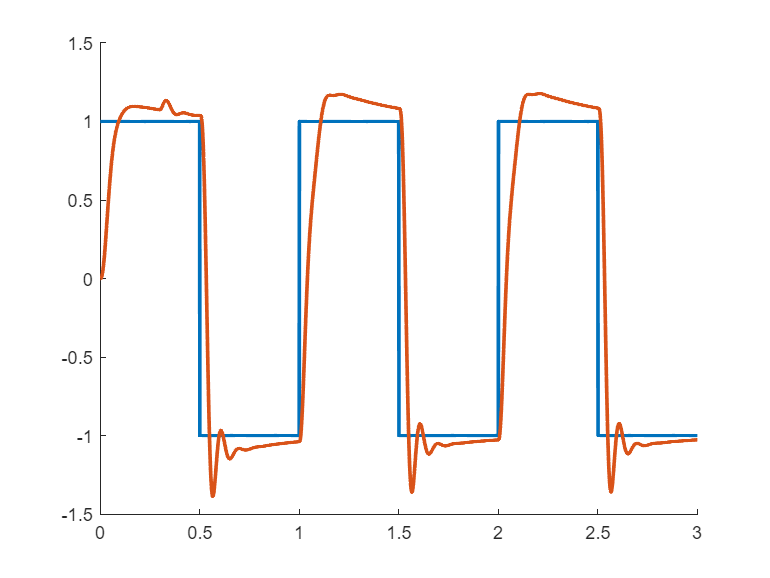

clf
hold on
plot(time,real_position,'LineWidth',2);
plot(time,y,'LineWidth',2);
hold off